# Gaussian Elimination with Backward Substitution

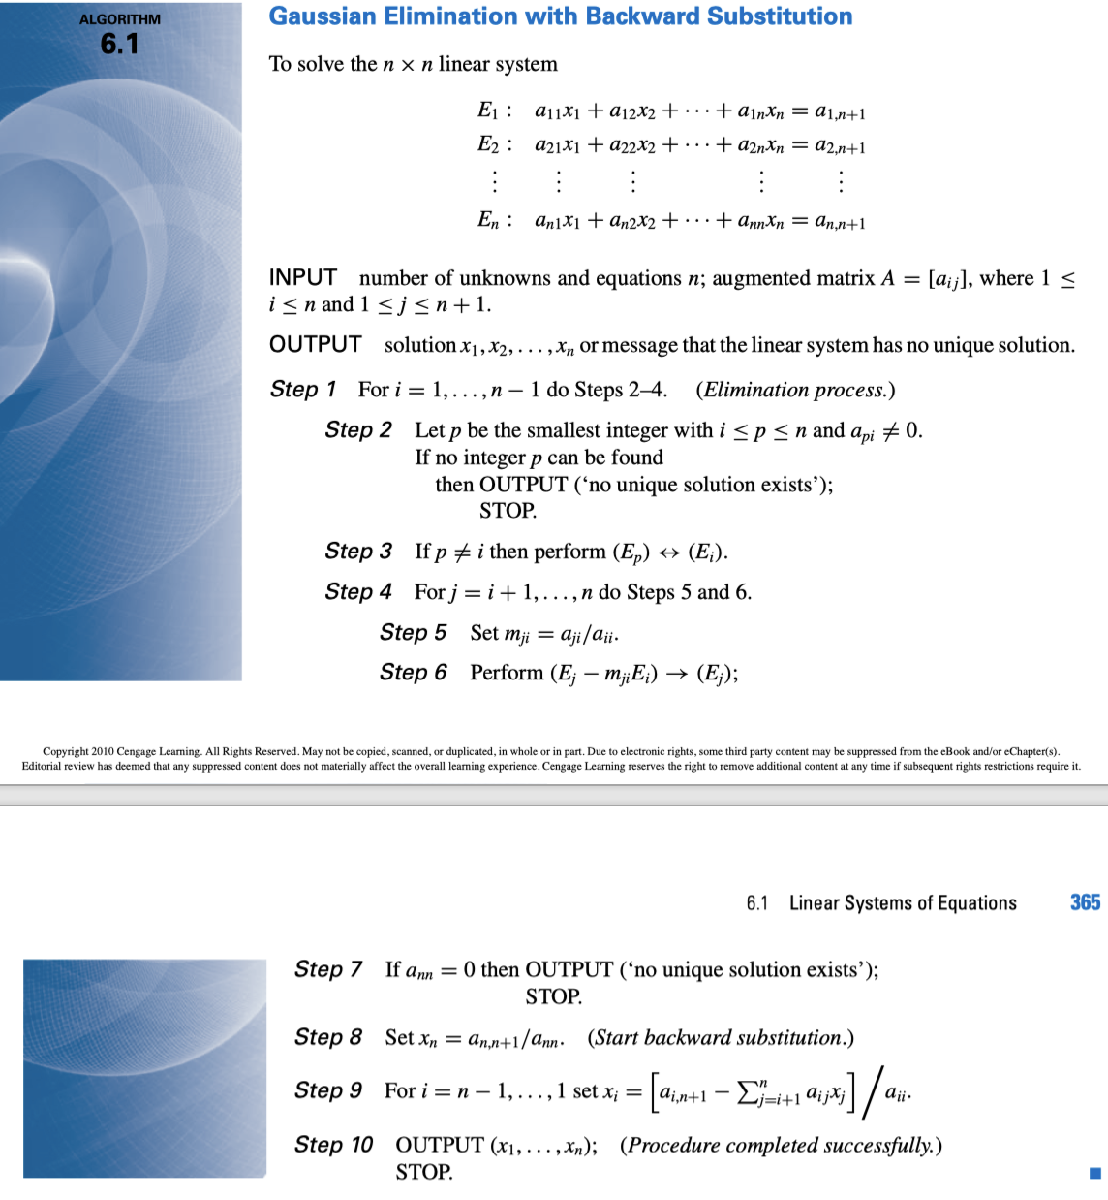

clc;clear;close all;

A=[3,-4;-5,2];
Aau=A;

Ag={};                                                  %Create a cell array to store each matrix                                             %Generate the augmented matrix
Ag{1}=Aau;                                              %Store the first initial matrix
[n,b]=size(A);
m=[];
for i=1:n-1
    %Check and switch to check pivot to be not 0
    p=i;
    while Aau(p,i)==0 & p <= n-1    
        p=p+1;
    end
    if p==n & Aau(p,i)==0
        disp("No unique solution found, please check");
        break
    end
    Atemp=Aau(i,:);
    Aau(i,:)=Aau(p,:);
    Aau(p,:)=Atemp;
    for j=i+1:n
        m(j,i)=Aau(j,i)/Aau(i,i);
        Aau(j,:)=Aau(j,:)-m(j,i).*Aau(i,:);
    end
    Ag{i +1}=Aau;
end


% modify into LU factorization

L2=eye(n);
L1=zeros(n,n);
L1(2:n,1:n-1)=m(2:end,:);
L=L1+L2;
disp(L);
U=Aau(:,1:n);